directory = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bilder\1_Runde_Schilder\Geschwindigkeitsbegrenzungen\Geschwindigkeitsbegrenzung 30\Ackerstraße";
cd(directory);      % Arbeitsverzeichnis setzen


I = imread("Verkehrsberuhigter_Bereich-2025-06-06__9.jpg");

%imshow(I);

grayImage = rgb2gray(I);
%imshowpair(I, grayImage, method = "montage");
% imwrite(grayImage, "test.jpg");
grayImagefilter = imgaussfilt(grayImage, 2); % Rauschentfernung 
edges = edge(grayImage, 'Canny'); % Verwendung des Canny-Algorithmus
%imshowpair(grayImagefilter, edges, method = "montage");
%imshowpair(grayImagefilter, grayImage, method = "montage");
% imwrite(grayImagefilter, "test.jpg");
binaryImg = imbinarize(grayImage);
%imshowpair(binaryImg, grayImage, method = "montage");
% imwrite(binaryImg, "test2.jpg");


Test Kreiserkennung

imshow(I);
[centers, radii] = imfindcircles(I, [15, 50], 'Sensitivity', 0.90)

centers = 1.0e+03 *

    1.0843    0.7066
    0.9934    0.7038


radii =    20.1544
   16.9946


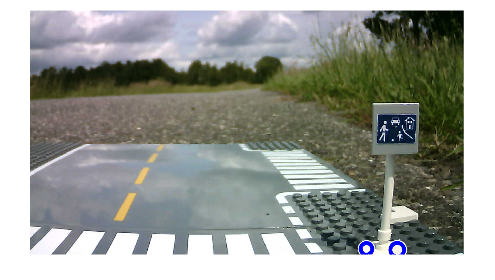

viscircles(centers, radii,'EdgeColor','b');

imshow(grayImage);
[centers, radii] = imfindcircles(grayImage, [15, 50], 'Sensitivity', 0.9)

centers = 1.0e+03 *

    1.0843    0.7066
    0.9934    0.7038


radii =    20.1544
   16.9946


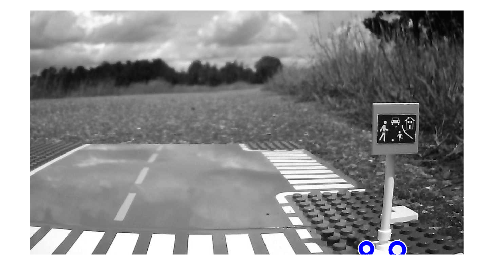

viscircles(centers, radii,'EdgeColor','b');

% imshow(I);
% [centers, radii] = imfindcircles(I, [15, 100], 'Sensitivity', 0.9)
% viscircles(centers, radii,'EdgeColor','b');
% imshow(grayImage);
% [centers, radii] = imfindcircles(grayImage, [15, 100], 'Sensitivity', 0.9)
% viscircles(centers, radii,'EdgeColor','b');
% imshow(I);
% [centers, radii] = imfindcircles(I, [15, 200], 'Sensitivity', 0.9)
% viscircles(centers, radii,'EdgeColor','b');
% imshow(grayImage);
% [centers, radii] = imfindcircles(grayImage, [15, 200], 'Sensitivity', 0.9)
% viscircles(centers, radii,'EdgeColor','b');